# Management of the Manual Material Handling Dataset for Biomechanical and Ergonomics Analysis dataset 

## Zenodo dataset DOI: 10.5281/zenodo.4633087

## If you use the dataset, please cite the paper "A Dataset of Human Motion and Muscular Activities in Manual Material Handling tasks for Biomechanical and Ergonomic Analyses." (Bassani et al., IEEE Sensors, submitted).

This script allows the user to use the data included in the dataset.

The following steps provide an implementation of a procedure to download, parse and process the data.

## Step 1 - Select the data you want to download from the [Zenodo link](https://zenodo.org/record/4633087#.YOLSuugzabg)

To use the dataset you must select at least the "*EMG_Data*", the "*EMG_Labels*", the "*mvnx_files*", and the "*mvnx_Labels*" zipped files.

This step create a folder (*MMH_Dataset*) where the selected motion and EMG data are copied from the online dataset. Already existing data are not downloaded again.

% MMH_Dataset directory creation
MMH_Dataset_dir = fullfile(cd,'MMH_Dataset');
if ~exist(MMH_Dataset_dir, 'dir')
    mkdir(MMH_Dataset_dir)
end
% Creating the file metadata table containing the files' names and links
file_link_list = getAttribute(findElement(htmlTree(webread('https://zenodo.org/record/4633087#.YOLSuugzabg')),"LINK[href$="".7z""]"),"href");
Metadata = table;
for i = 1:size(file_link_list)    
    file_link_field = split(file_link_list(i),'/'); 
    file = split(file_link_field(end),'.');
    Metadata.file_name{i,1} = file(1);
    Metadata.MMH_Dataset_file_dir{i,1} = fullfile(MMH_Dataset_dir,Metadata.file_name{i,1});
    clear file_link_field file
end
% Creation of the Dialog List Box to select the files to download and the wait bar to visualize the downloading process
file_sel = listdlg('ListString',Metadata.file_name,'Name','File Selection','ListSize',[300,150], ...
    'PromptString','Select the data you want to download from the zenodo link.');
down = 0;
for i = 1:size(file_sel,2) 
    if exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}+".7z", 'file')
        down=down+1;        
    end
end
if down == size(file_sel,2) && down > 1
    waitfor(msgbox('Files selected already downloaded!'));
end
for i = 1:size(file_sel,2) 
    if ~exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}+".7z", 'file') 
        if i == 1
            hWaitbar = waitbar(0, 'Please wait...','DefaultTextInterpreter','none');
        end
        waitbar(0.14*i,hWaitbar,"Downloading "+Metadata.file_name{file_sel(i),1}+" data",'DefaultTextInterpreter','none');        
        pause(.5)       
        data{i} = websave(Metadata.MMH_Dataset_file_dir{file_sel(i),1}, file_link_list(file_sel(i)));   % Downloading the data
        if i == size(file_sel,2)
            waitbar(1,hWaitbar,"Downloading "+Metadata.file_name{file_sel(i),1}+" data",'DefaultTextInterpreter','none');        
            pause(.5)
            delete(hWaitbar);
        end
    end          
end

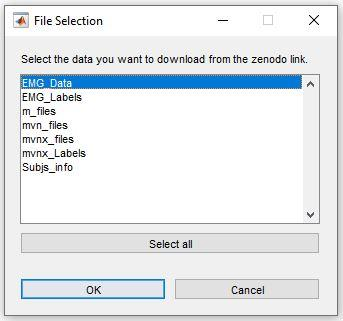 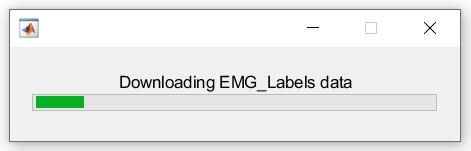

## Step 2 - Extract the contents of the zipped files downloaded

### This step requires [7-Zip](https://www.7-zip.org/download.html) in the system path

In this step the zipped folder downloaded are extracted if not already existing. 

% Creation of the message boxes needed and the wait bar to visualize the folder extraction
down = 0; extr = 0;
for i = 1:size(file_sel,2) 
    if exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}+".7z", 'file')
        down=down+1;        
    end
    if exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}, 'dir')
        extr=extr+1;        
    end
end
if down == size(file_sel,2) && down > 1
    if extr == size(file_sel,2) && extr > 0
        waitfor(msgbox('Files already extracted!'));
    end
else
    for i = 1:size(file_sel,2)
        if ~exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}+".7z", 'file')
            msgbox("File "+Metadata.file_name{file_sel(i),1}+" not downloaded!");
        end
    end
end
for i = 1:size(file_sel,2) 
    if exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}+".7z", 'file') && ~exist(Metadata.MMH_Dataset_file_dir{file_sel(i),1}, 'dir')
        if i == 1
            hWaitbar = waitbar(0, 'Please wait...','DefaultTextInterpreter','none');
        end
        waitbar(0.14*i,hWaitbar,"Extracting "+Metadata.file_name{file_sel(i),1}+" data",'DefaultTextInterpreter','none');        
        pause(.5)       
        [status,result] = system("7z.exe" + " x "  + Metadata.MMH_Dataset_file_dir{file_sel(i),1}+".7z" + " -o" + Metadata.MMH_Dataset_file_dir{file_sel(i),1}); % Extracting the data
        if status
            waitfor(msgbox('Files not extracted!'));
        end
        if i == size(file_sel,2)
            waitbar(1,hWaitbar,"Extracting "+Metadata.file_name{file_sel(i),1}+" data",'DefaultTextInterpreter','none');        
            pause(.5)
            delete(hWaitbar);
        end
    end         
end


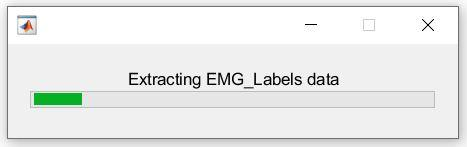

## Step 3- Select the subject(s) you want to process

The subjects are 14 and multiple subjects can be selected. 

All subjects are selected in case of no subject selection.

% Creation of the Dialog List Box to select the subject(s)
EMG_Data_dir = Metadata.MMH_Dataset_file_dir{1,1}+'\Data'; % Directory of the EMG data
d_EMG = dir(EMG_Data_dir);
d_ = struct2cell(d_EMG);
subj_sel = listdlg('ListString',convertCharsToStrings(d_(1,3:end)),'Name','Subject Selection','ListSize',[250,200], ...
    'PromptString','Select the subject you want to process');
clear d_
if size(subj_sel,2) > 0
    subj_sel = subj_sel+2;
else
    subj_sel = 3:size(d_EMG,1);
end

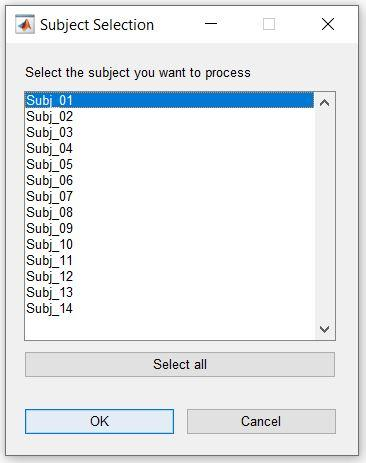

## Step 4 - Select the trials you want to process

The trials are 37:

- 16 Isokinetic trails;

- 9 Bimanual MMH trials;

- 12 One-handed MMH trials.

All trials will be selected in case of no trial selection.

% Creation of the Dialog List Box to select the trial(s)
trial_dir_list = dir(fullfile(Metadata.MMH_Dataset_file_dir{5,1},convertCharsToStrings(d_EMG(subj_sel(1)).name)));
for i = 3:size(trial_dir_list,1)
    trial_list{i-2,:} = trial_dir_list(i).name(9:end-5);
end
trial_sel = listdlg('ListString',convertCharsToStrings(trial_list),'Name','Trial Selection','ListSize',[250,300], ...
    'PromptString','Select the trials you want to process');
if size(trial_sel,2) > 0
    trial_sel = trial_sel+2;
else
    trial_sel = 3:size(trial_dir_list,1);
end

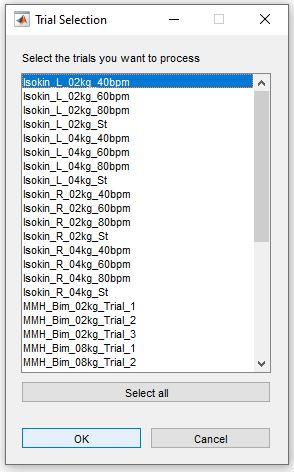

## Step 5 - Load motion data in the MATLAB workspace

### To run this step, the function load_mvnx.m provided by [Xsens](https://base.xsens.com/knowledgebase/s/article/MATLAB-script-to-read-MVNX-files?language=en_US) must be in the path.

In this step the mvnx files are imported in MATLAB by means of the load_mvnx.m function.

The data structure is created in this step. Data includes as many fields as the selected subjects and for each of them there is a sub field for every selected activity plus the MVC.

In the activites sub fields the motion field is created with sub fields *mvnx_labels* and *Motion_data*. The mvnx labels correspond to the motion labels described in the paper, whereas Motion_data is the structure created by the the load_mvnx function.

This step create a folder (*Data_Post*) in the *MMH_Dataset* directory where the data structure of each subject selected will be saved at the end of the Step 6.

The code of this step highlights where the user can include an additional motion processing function.

% Creation of the folder to save the data structure of each subject selected 
processedData_dir = MMH_Dataset_dir + "\Data_Post";                                     
if ~exist(processedData_dir, 'dir')
    mkdir(processedData_dir)
end
% The following code explores the motion data folder (mvnx_files) to add the motion data and labels of the selected subjects and trials to the data structure
mvnx_Labels_dir = Metadata.MMH_Dataset_file_dir{6,1}+'\Labels';  % Directory of the motion labels
d_mvnx = dir(Metadata.MMH_Dataset_file_dir{5,1});
s_last = size(subj_sel,2);
for I1 = 1:length(d_mvnx)
    s_p = s_last;
    t_last = size(trial_sel,2);
    subject_num = d_mvnx(I1).name;  
    subject_dir = fullfile(Metadata.MMH_Dataset_file_dir{5,1},subject_num);
    if exist(subject_dir,'dir')
        if subject_num == "." || subject_num == ".."
            continue
        elseif s_last == 0
            break
        else
            for jj = 1:size(subj_sel,2)
                if s_last == s_p
                    if subject_num == convertCharsToStrings(d_EMG(subj_sel(jj)).name)
                        s_last = s_last-1;                      
                        processedData_name = [subject_num, '.mat'];
                        file_path = fullfile(processedData_dir, processedData_name);
                        subject_dir_list = dir(subject_dir);                     
                        for I2 = 1:length(subject_dir_list)
                            t_p = t_last;
                            file_name = subject_dir_list(I2).name;
                            file_dir = fullfile(subject_dir,file_name);
                            if exist(file_dir,'file')
                                if file_name == "." || file_name == ".." 
                                    continue
                                elseif t_last == 0
                                    break
                                else
                                    for jjj = 1:size(trial_sel,2)   
                                        if t_last == t_p
                                            if file_name(9:end-5) == convertCharsToStrings(trial_dir_list(trial_sel(jjj)).name(9:end-5)) 
                                                t_last = t_last-1;                      
                                                labels_name = [file_name(1:end-5),'_mvnx_labels.csv'];
                                                activity_set = file_name(1:end-5);                                             
                                                labels_dir = fullfile(mvnx_Labels_dir,subject_num,labels_name);
                                                Data.(subject_num).(activity_set).Motion.mvnx_labels = readtable(labels_dir);  % Adding the motion labels to the data structure
                                                Data.(subject_num).(activity_set).Motion.Motion_data = load_mvnx(file_dir);    % Adding the motion data to the data structure                                             
                                                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                                %%%%%%%%%%%%%%%%%%%%%%%%%%  HERE MOTION PROCESSING FUNCTIONS CAN BE ADDED  %%%%%%%%%%%%%%%%%%%%%%%%%%
                                                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%                                                
                                            end
                                        end
                                    end
                                end      
                            end
                        end
                    end
                end
            end
        end
    end
end 


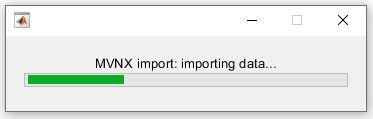

## Step 6 - Load and process the EMG data in the MATLAB workspace

This step imports the EMG data in the MATLAB workspace and provides the basic processing steps.

In this step, the MVC data available for each selected subject are processed and added to the subject field of the data structure (field *MVC*).

For each subject fields and activities sub fields of the data structure, created in Step 5, the EMG subfields corresponding to the performed activities (*EMG_L_Arm* and *EMG_R_Arm*) are created.

In EMG field the following sub fields are created: 

- *EMG_labels*: it includes the EMG data labels as described in the paper.

- *EMG_data*: this is a table with colums corresponding to the sEMG *csv* files described in the paper. Column numbering (1...8) corresponds to the following muscles: Extensor digitorum (1-2), Brachioradialis (3-4), Triceps brachii (5-6), Biceps brachii (7-8).

- *Metadata*: it contains the number of samples of the trial, its duration, and the measured data acquisition frequency.

- *EMG_data_processed*: it includes 7 fields corresponding to the processing steps described in the Section 4 of the paper. 

% Parameters for the filtering stages of the EMG data
fm = ones(1,2)/2; % Moving average filter
wl = 250;         % Envelope window

### Extracting MVC data

EMG_Labels_dir = Metadata.MMH_Dataset_file_dir{2,1}+'\Labels'; % Directory of the EMG labels
% The following code explores the EMG data folder (EMG_Data\Data) to add the EMG data and labels of the MVC of the selected subjects to the data structure, and to process the MVC data.
s_last = size(subj_sel,2);
for I1 = 1:length(d_EMG)
    s_p = s_last;
    subject_num = d_EMG(I1).name;  
    subject_dir = fullfile(EMG_Data_dir,subject_num);
    if exist(subject_dir,'dir') 
        if subject_num == "." || subject_num == ".."
            continue
        elseif s_last == 0
            break
        else
            for jj = 1:size(subj_sel,2)
                if s_last == s_p
                    if subject_num == convertCharsToStrings(d_EMG(subj_sel(jj)).name)
                        s_last = s_last-1;              
                        processedData_name = [subject_num, '.mat'];
                        file_path = fullfile(processedData_dir, processedData_name);
                        subject_dir_list = dir(subject_dir);                          
                        for I2 = 1:length(subject_dir_list)
                            file_name = subject_dir_list(I2).name;
                            file_dir = fullfile(subject_dir,file_name);
                            if exist(file_dir,'file')
                                if file_name == "." || file_name == ".." 
                                    continue
                                elseif file_name(9:11) == "MVC"
                                    if file_name(13) == "A"
                                        mvc_labels_name = [file_name(1:22),'range.csv'];
                                        mvc_labels_dir = fullfile(EMG_Labels_dir,subject_num,mvc_labels_name);
                                        side = file_name(17);
                                        activity_set = file_name(1:17);
                                    else
                                        if file_name(13) == "I"
                                            mvc_labels_name = [file_name(1:25),'range.csv'];
                                        else
                                            mvc_labels_name = [file_name(1:26),'range.csv'];
                                        end
                                        mvc_labels_dir = fullfile(EMG_Labels_dir,subject_num,mvc_labels_name);
                                        if file_name(13:15) == "Iso"
                                            side = file_name(20);
                                            activity_set = file_name(1:20);
                                        else
                                            side = file_name(21);
                                            activity_set = file_name(1:21);
                                        end
                                    end
                                    Data.(subject_num).MVC.(activity_set).EMG_labels = readtable(mvc_labels_dir);    % Adding the MVC labels to the data structure
                                    Data.(subject_num).MVC.(activity_set).EMG_data = readtable(file_dir);            % Adding the MVC data to the data structure              
                                    Data.(subject_num).MVC.(activity_set).Metadata.Sample_num = size(Data.(subject_num).MVC.(activity_set).EMG_data.Time,1);                                                                 % Trial sample number
                                    Data.(subject_num).MVC.(activity_set).Metadata.Duration_s = (Data.(subject_num).MVC.(activity_set).EMG_data.Time(end) - Data.(subject_num).MVC.(activity_set).EMG_data.Time(1)) / 1000;  % Trial time duration (s)
                                    Data.(subject_num).MVC.(activity_set).Metadata.Frequency = 1 / (Data.(subject_num).MVC.(activity_set).Metadata.Duration_s / Data.(subject_num).MVC.(activity_set).Metadata.Sample_num);  % Trial data acquisition frequency (Hz)                            
                                    fNotch = designfilt('bandstopiir','FilterOrder',2, 'HalfPowerFrequency1',49,'HalfPowerFrequency2',51, 'DesignMethod','butter','SampleRate',Data.(subject_num).MVC.(activity_set).Metadata.Frequency); % Notch filter                                     
                                    Fn = Data.(subject_num).MVC.(activity_set).Metadata.Frequency/2; Fl = 20; Fh = Fn-1; Wp = [Fl  Fh]/Fn;  [b,a] = butter(2,Wp,'bandpass');                                                              % Bandpass filter                                                                                         
                                    for i = 1:8
                                        Data.(subject_num).MVC.(activity_set).EMG_data_processed.Notch_V(:,i) = filtfilt(fNotch,Data.(subject_num).MVC.(activity_set).EMG_data.(['Raw_V_',num2str(i)]));            % Filtering 50Hz interference
                                        Data.(subject_num).MVC.(activity_set).EMG_data_processed.Butter_V(:,i) = filtfilt(b,a,Data.(subject_num).MVC.(activity_set).EMG_data_processed.Notch_V(:,i));               % Buttering the voltages
                                        Data.(subject_num).MVC.(activity_set).EMG_data_processed.Avgmob_V(:,i) = filtfilt(fm,1,Data.(subject_num).MVC.(activity_set).EMG_data_processed.Butter_V(:,i));             % Smoothing with moving average filter
                                        Data.(subject_num).MVC.(activity_set).EMG_data_processed.Rect_V(:,i) = abs(Data.(subject_num).MVC.(activity_set).EMG_data_processed.Avgmob_V(:,i));                         % Rectifying the voltages
                                    end                                    
                                    for i = 1:8
                                        [Up_V(:,i),Low_V(:,i)] = envelope(Data.(subject_num).MVC.(activity_set).EMG_data_processed.Rect_V(:,i), wl, 'rms');
                                        Data.(subject_num).MVC.(activity_set).Metadata.mvc(1,i) = mean(Up_V(Data.(subject_num).MVC.(activity_set).EMG_labels.Start_Frame:Data.(subject_num).MVC.(activity_set).EMG_labels.End_Frame,i)); % Extracting the mvc 
                                    end
                                    clear Up_V Low_V
                                end
                            end
                        end
                    end
                end
            end
        end
    end
end

### Processing trial data

% Creation of a structure containing the EMG trials names with corresponding motion trial names. Needed for the Bimanual trials where the EMG data are present for both arms.
ii = 0;
for jjj = 1:size(trial_sel,2)
    ii=ii+1;                    
    mvnx_trial_sel = trial_dir_list(trial_sel(jjj)).name(1:end-5);
    if (size(mvnx_trial_sel,2) <= 27 && mvnx_trial_sel(9) == "I") || (size(mvnx_trial_sel,2) > 27 && mvnx_trial_sel(13) == "O")     
        EMG_trial_sel(ii).trial_name = convertCharsToStrings(mvnx_trial_sel);
        EMG_trial_sel(ii).EMG_trial_name = convertCharsToStrings(mvnx_trial_sel)+"_EMG_data.csv";
    elseif size(mvnx_trial_sel,2) > 27 && mvnx_trial_sel(13) == "B"
        EMG_trial_sel(ii).trial_name = convertCharsToStrings(mvnx_trial_sel);
        EMG_trial_sel(ii).EMG_trial_name = convertCharsToStrings(mvnx_trial_sel(1:16))+"L_"+convertCharsToStrings(mvnx_trial_sel(17:end))+"_EMG_data.csv";
        ii=ii+1;
        EMG_trial_sel(ii).trial_name = convertCharsToStrings(mvnx_trial_sel);
        EMG_trial_sel(ii).EMG_trial_name = convertCharsToStrings(mvnx_trial_sel(1:16))+"R_"+convertCharsToStrings(mvnx_trial_sel(17:end))+"_EMG_data.csv";
    end
end
% The following code explores the EMG data folder (EMG_Data\Data) to add the EMG data and labels of the selected subjects and trials to the data structure, and to process the EMG data.
for j = 1:size(EMG_trial_sel,2)
    EMG_trial_sel(j).EMG_trial_name = convertStringsToChars(EMG_trial_sel(j).EMG_trial_name);
end
s_last = size(subj_sel,2);
for I1 = 1:length(d_mvnx)
    s_p = s_last;
    t_last = size(EMG_trial_sel,2);
    subject_num = d_EMG(I1).name;  
    subject_dir = fullfile(EMG_Data_dir,subject_num);
    if exist(subject_dir,'dir')
        if subject_num == "." || subject_num == ".."
            continue
        elseif s_last == 0
            break
        else
            for jj = 1:size(subj_sel,2)
                if s_last == s_p
                    if subject_num == convertCharsToStrings(d_EMG(subj_sel(jj)).name)
                        s_last = s_last-1;          
                        processedData_name = [subject_num, '.mat'];
                        file_path = fullfile(processedData_dir, processedData_name);
                        subject_dir_list = dir(subject_dir);                             
                        for I2 = 1:length(subject_dir_list)
                            t_p = t_last;
                            file_name = subject_dir_list(I2).name;  
                            file_dir = fullfile(subject_dir,file_name);
                            if exist(file_dir,'file')
                                if file_name == "." || file_name == ".." 
                                    continue
                                elseif t_last == 0
                                    break
                                else
                                    for jjj = 1:size(EMG_trial_sel,2)
                                        if t_last == t_p
                                            if file_name(9:end-13) == convertCharsToStrings(EMG_trial_sel(jjj).EMG_trial_name(9:end-13))
                                                t_last = t_last-1;                                                                                    
                                                if file_name(9) == "I" 
                                                    side = file_name(16);
                                                    if file_name(23) == "S"
                                                        labels_name = [file_name(1:29),'labels.csv'];
                                                        activity_set = file_name(1:24);
                                                    else 
                                                        labels_name = [file_name(1:32),'labels.csv'];
                                                        activity_set = file_name(1:27);
                                                    end
                                                    if subject_num == "Subj_01" || subject_num == "Subj_11"
                                                        mvc_activity_set = [subject_num, '_MVC_', file_name(9:16)];
                                                    end
                                                elseif file_name(9) == "M"
                                                    side = file_name(17);
                                                    labels_name = [file_name(1:35),'labels.csv'];
                                                    activity_set = file_name(1:30);
                                                    if subject_num == "Subj_01" || subject_num == "Subj_11"
                                                        mvc_activity_set = [subject_num, '_MVC_', file_name(9:17)];
                                                    end
                                                end
                                                if subject_num ~= "Subj_01" && subject_num ~= "Subj_11"
                                                    mvc_activity_set = [subject_num, '_MVC_All_', side];
                                                end
                                                labels_dir = fullfile(EMG_Labels_dir,subject_num,labels_name);
                                                 
                                                EMG_Data.EMG_labels = readtable(labels_dir);                         % Adding the EMG labels to the data structure
                                                EMG_Data.EMG_data = readtable(file_dir);                             % Adding the EMG data to the data structure
                                                mvc = Data.(subject_num).MVC.(mvc_activity_set).Metadata.mvc;        % mvc                                                                      
                                                EMG_Data.Metadata.Sample_num = size(EMG_Data.EMG_data.Time,1);                                         % Trial sample number
                                                EMG_Data.Metadata.Duration_s = (EMG_Data.EMG_data.Time(end) - EMG_Data.EMG_data.Time(1)) / 1000;       % Trial time duration (s)
                                                EMG_Data.Metadata.Frequency = 1 / (EMG_Data.Metadata.Duration_s / EMG_Data.Metadata.Sample_num);       % Trial data acquisition frequency (Hz) 
                                                fNotch = designfilt('bandstopiir','FilterOrder',2, 'HalfPowerFrequency1',49,'HalfPowerFrequency2',51, 'DesignMethod','butter','SampleRate',EMG_Data.Metadata.Frequency);   % Notch filter 
                                                Fn = EMG_Data.Metadata.Frequency/2; Fl = 20; Fh = Fn-1; Wp = [Fl  Fh]/Fn; [b,a] = butter(2,Wp,'bandpass');                                                                 % Bandpass filter                                                                        
                                                for i = 1:8
                                                    EMG_Data.EMG_data_processed.Notch_V(:,i) = filtfilt(fNotch,EMG_Data.EMG_data.(['Raw_V_',num2str(i)]));            % Filtering 50Hz interference
                                                    EMG_Data.EMG_data_processed.Butter_V(:,i) = filtfilt(b,a,EMG_Data.EMG_data_processed.Notch_V(:,i));               % Buttering the voltages
                                                    EMG_Data.EMG_data_processed.Avgmob_V(:,i) = filtfilt(fm,1,EMG_Data.EMG_data_processed.Butter_V(:,i));             % Smoothing with moving average filter
                                                    EMG_Data.EMG_data_processed.Rect_V(:,i) = abs(EMG_Data.EMG_data_processed.Avgmob_V(:,i));                         % Rectifying the voltages
                                                end                                                
                                                for i = 1:8
                                                    EMG_Data.EMG_data_processed.Norm_V(:,i) = EMG_Data.EMG_data_processed.Rect_V(:,i) * 100 / mvc(i);                     % Normalization        
                                                    [EMG_Data.EMG_data_processed.rms(:,i), ylow(:,i)] = envelope(EMG_Data.EMG_data_processed.Avgmob_V(:,i), wl, 'rms');   % RMS
                                                    EMG_Data.EMG_data_processed.rms_ratio(:,i) = EMG_Data.EMG_data_processed.rms(:,i) * 100 / mvc(i);                     % Normalization of the RMS        
                                                end
                                                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                                %%%%%%%%%%%%%%%%%%%%%%%%%%  HERE EMG PROCESSING FUNCTIONS CAN BE ADDED  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                                                side = "EMG_"+side+"_Arm";
                                                tname = convertStringsToChars(EMG_trial_sel(jjj).trial_name); tname = tname(9:end); tname = convertCharsToStrings(subject_num)+"_"+convertCharsToStrings(tname);
                                                Data.(subject_num).(tname).(side) = EMG_Data;
                                                clear EMG_Data ylow
                                                subj_Data = {Data.(subject_num)};                         
                                                save(file_path, 'subj_Data', '-v7.3', '-nocompression')   % Saving the data structure of each subject selected in the Data_Post created at the beginning of Step 5.
                                                clear subj_Data
                                            end
                                        end
                                    end
                                end
                            end
                        end                                                                 
                    end
                end
            end
        end
    end
end               

## Step 7 - Plotting sEMG signal acquired from the Biceps brachii and shoulder flexion angle  

This step provides an example of visualization of the EMG and motion data.

Further processing steps can be added by the user.

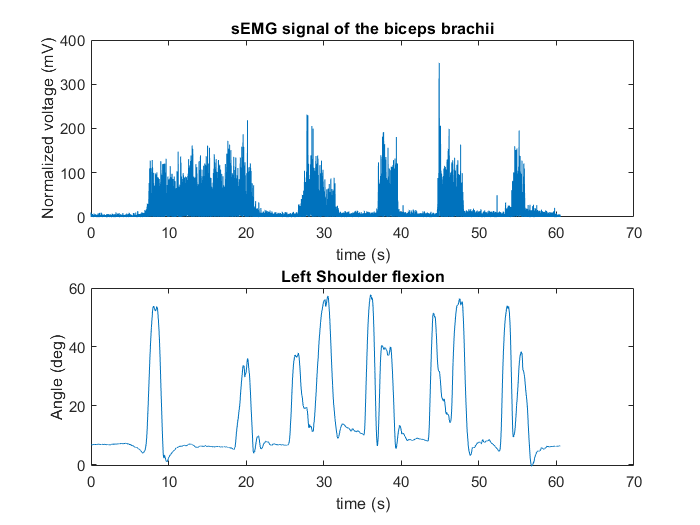

subject_num = convertCharsToStrings(d_EMG(subj_sel(1)).name);       % Subject number 
activity_set = convertCharsToStrings(mvnx_trial_sel);               % Trial name 
for kk = 1:size(Data.(subject_num).(activity_set).Motion.Motion_data.frame,2)
    time_mvnx(kk,:)  = str2num(Data.(subject_num).(activity_set).Motion.Motion_data.frame(kk).ms) + 3600000; % Time of the motion data (ms)
end
jointAngleErgo = Data.(subject_num).(activity_set).Motion.Motion_data.ergonomicJointAngle(2).jointAngleErgo;                                            % T8_LeftUpperArm ergonomic joint angle 
range_mvnx = Data.(subject_num).(activity_set).Motion.mvnx_labels.Start_Frame(1):Data.(subject_num).(activity_set).Motion.mvnx_labels.End_Frame(end);   % Motion data range
t = (time_mvnx(range_mvnx)-time_mvnx(range_mvnx(1)))*10^-3;                                                                                             % Motion data time range (s)
range_EMG = Data.(subject_num).(activity_set).(side).EMG_labels.Start_Frame(1):Data.(subject_num).(activity_set).(side).EMG_labels.End_Frame(end);      % EMG data range
t_EMG = (Data.(subject_num).(activity_set).(side).EMG_data.Time(range_EMG)-Data.(subject_num).(activity_set).(side).EMG_data.Time(range_EMG(1)))*10^-3; % EMG data time range (s)
% Plotting the Normalized voltage of the channel 8 (Biceps brachii) and of the Left Shoulder flexion angle
figure
subplot(2,1,1)
plot(t_EMG,Data.(subject_num).(activity_set).(side).EMG_data.Norm_V_8(range_EMG))
xlabel('time (s)')
ylabel('Normalized voltage (mV)')
title('sEMG signal of the Biceps brachii')
subplot(2,1,2)
plot(t,jointAngleErgo(range_mvnx,3))
xlabel('time (s)')
ylabel('Angle (deg)')
title('Left Shoulder flexion')